disp('============IDENTIFICAÇÃO CONVERSOR BUCK (bancada)============');

============IDENTIFICAÇÃO CONVERSOR BUCK (bancada)============


disp('Dados ensaio: 20KHz ; Ts = 50us');

Dados ensaio: 20KHz ; Ts = 50us


disp('Laboratorio LINCE');

Laboratorio LINCE


disp('Discente: Luiz Felipe Souza de Lima Silva');

Discente: Luiz Felipe Souza de Lima Silva


1. Inicialização e declaração de parametros:

clear, clc, close all
%Importação dos dados de saída e entrada a partir do CSV
dados_csv = readmatrix('Teste02 - Teste02.csv.csv');

%Remoção eventuais linhas vazias/NaN no final do arquivo
dados_csv = dados_csv(~isnan(dados_csv(:,1)), :);

Nd = 500;
Ts = 5.0e-5;

disp('------------------------------------------------------');

------------------------------------------------------


disp('PARAMETROS DE PROJETO:');

PARAMETROS DE PROJETO:



%Parametros 
Fs = 20000

Fs = 20000

d =  0.3

d = 0.3000

Vs = 30

Vs = 30

Cp = 0.000041666667

Cp = 4.1667e-05

L = 0.000470

L = 4.7000e-04

R = 10.0

R = 10

num = Vs/(Cp*L);
den = [1,1/(Cp*R) , 1/(Cp*L)];


2. Função de transferencia matematica:

disp('------------------------------------------------------');

------------------------------------------------------


disp('FUNÇÃO DE TRANSFERENCIA MODELADA ANALITICAMENTE:');

FUNÇÃO DE TRANSFERENCIA MODELADA ANALITICAMENTE:



Gs = tf(num,den)

Gs =
 
         1.532e09
  -----------------------
  s^2 + 2400 s + 5.106e07
 
Continuous-time transfer function.
Model Properties



disp('Polos e zeros:');

Polos e zeros:



pole(Gs)

ans = 1.0e+03 *

  -1.2000 + 7.0444i
  -1.2000 - 7.0444i




disp('Resposta ao Degrau:');

Resposta ao Degrau:


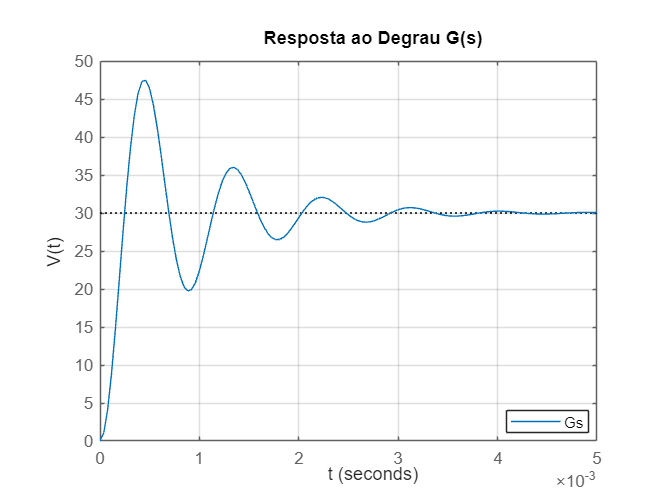


figure(1)
clf;
step(Gs)
xlabel('t'); ylabel('V(t)');
grid on; legend('Location', 'best');
title('Resposta ao Degrau G(s)') 


disp('Discretização de G(s) utilizando método "matched":');

Discretização de G(s) utilizando método "matched":


Gz = c2d(Gs, Ts ,'zoh')

Gz =
 
     1.821 z + 1.749
  ----------------------
  z^2 - 1.768 z + 0.8869
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties


disp('------------------------------------------------------');

------------------------------------------------------


3. Coleta de dados e Identificação:

disp('COLETA DE DADOS E IDENTIFICAÇÃO:');

COLETA DE DADOS E IDENTIFICAÇÃO:


%(Tempo, PRBS e Saída)
t = dados_csv(1:end-Nd, 1)';
u = dados_csv(Nd:end-1, 2)';
v = dados_csv(Nd:end-1, 3)';

%% Eliminação da componente DC do sistema

mu_u = mean(u);
mu_v = mean(v);
u = u - mu_u;
v = v - mu_v;

y = transpose(v); 

%% Relação gráfica de saída e entrada
disp('OBS.:Entrada num conjunto de 200 amostras.');

OBS.:Entrada num conjunto de 200 amostras.


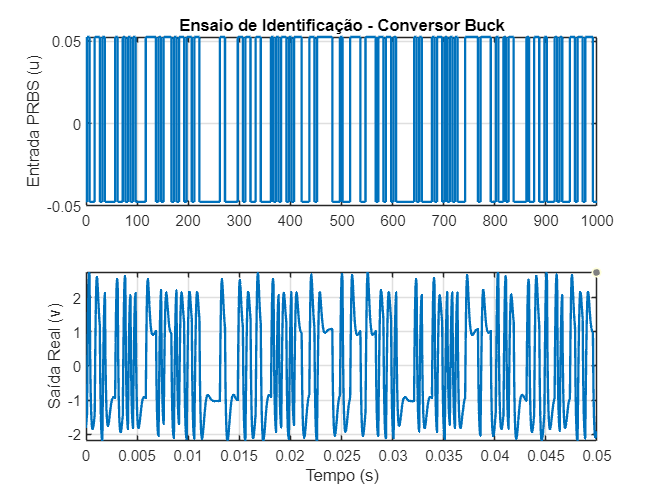

figure(2);
clf; 
subplot(2,1,1);
stairs(1:length(u), u, 'LineWidth', 1.4);
ylabel('Entrada PRBS (u)');
title('Ensaio de Identificação - Conversor Buck');
%xlim([0 1000]);   
%ylim([-0.08 0.08]); 
grid on;

subplot(2,1,2);
plot(t(1:length(v)), v, 'LineWidth', 1.4);
ylabel('Saída Real (v)');
xlabel('Tempo (s)');
grid on;


%% Construção matricial - regressores
Ns = numel(t);

M = zeros(Ns-3,4);

for n = 3:Ns
    phi = [y(n-1), y(n-2), u(n-1), u(n-2)];
    M(n, :) = phi;
end

theta = M\y;
a1 = theta(1);
a2 = theta(2);
b1 = theta(3);
b2 = theta(4);
ys = zeros(size(y));
ys(1:2) = y(1:2);

yp = M * theta;

disp('MODELO ARX OBTIDO:');

MODELO ARX OBTIDO:


Be = [0, b1, b2];
Ae = [1, -a1, -a2]; 
Gze = tf(Be, Ae, Ts)

Gze =
 
     -0.0206 z + 13.38
  -----------------------
  z^2 - 0.9208 z + 0.3491
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties


disp('------------------------------------------------------');

------------------------------------------------------


4. Analise e comparação de modelos:

%% Comparação ARX VS saída do sistema.
disp('ANALISE E COMPARAÇÃO DE MODELOS:');

ANALISE E COMPARAÇÃO DE MODELOS:


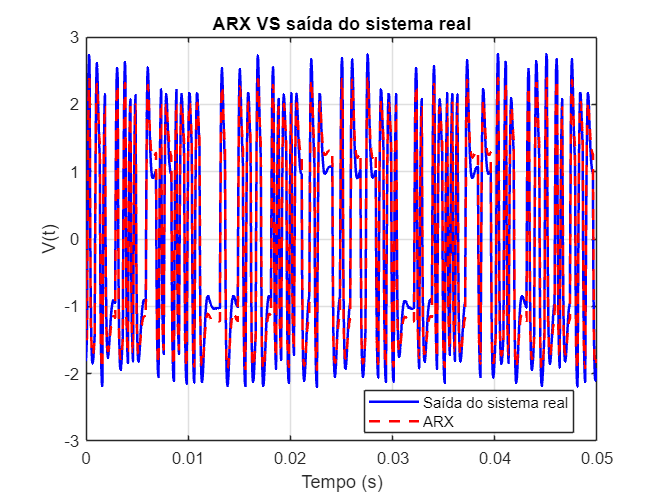

figure(3);
clf; 
plot(t, y, 'b', 'LineWidth', 1.5)
hold on
% 'r--' cria a linha tracejada vermelha para o modelo ARX
plot(t, yp, 'r--', 'LineWidth', 1.5)

legend('Saída do sistema real', 'ARX', 'Location', 'best');
hold off
grid on
xlabel('Tempo (s)');
ylabel('V(t)');
title('ARX VS saída do sistema real');

%xlim([0 0.05]);    %maximo de 50us
%ylim([-1.5 2]); 

disp('Funções de transferencia:');

Funções de transferencia:


disp('Gz modelo analitico');

Gz modelo analitico


Gz

Gz =
 
     1.821 z + 1.749
  ----------------------
  z^2 - 1.768 z + 0.8869
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties



disp('Gze modelo estimado');

Gze modelo estimado



Gze

Gze =
 
     -0.0206 z + 13.38
  -----------------------
  z^2 - 0.9208 z + 0.3491
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties


disp('------------------------------------------------------');

------------------------------------------------------


5.Ajuste R2:

%% Ajuste
disp('AJUSTE R2:');

AJUSTE R2:


R2 = 1 - sum((y - yp).^2)/sum((y - mean(y)).^2)

R2 = 0.9755

disp('------------------------------------------------------');

------------------------------------------------------


6. Cálculo do erro de predição/resíduo:

disp('Cálculo do erro de predição/resíduo:');

Cálculo do erro de predição/resíduo:


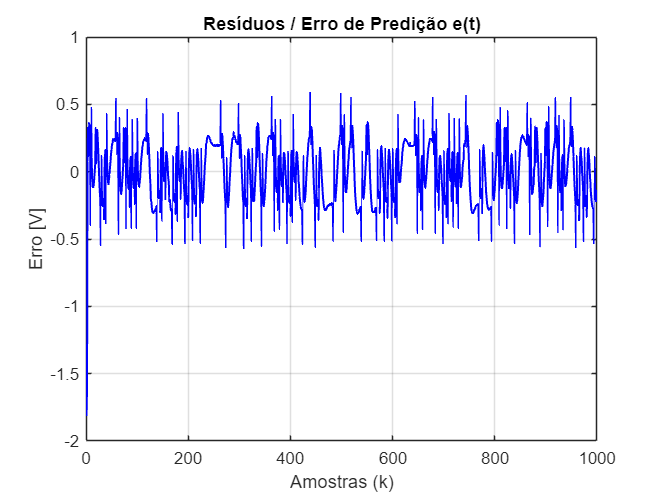

e = y - yp;

figure(6);
clf;
plot(e, 'b', 'LineWidth', 1.2);
grid on;
title('Resíduos / Erro de Predição e(t)');
xlabel('Amostras (k)');
ylabel('Erro [V]');

disp('------------------------------------------------------');

------------------------------------------------------


7. Analise de polos e zeros:

disp('ANALISE DE POLOS E ZEROS:');

ANALISE DE POLOS E ZEROS:



disp('BLUE - GZ');

BLUE - GZ


disp('RED - GZe');

RED - GZe


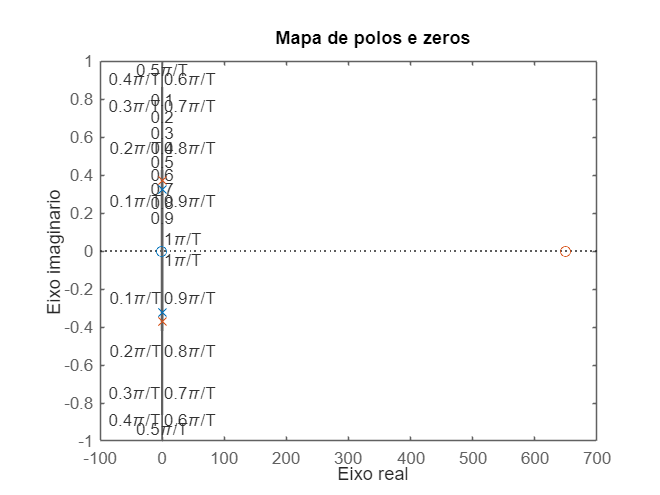


figure(7)
clf;
pzmap(Gz)
zgrid
hold on

pzmap(Gze)
hold off

xlabel('Eixo real');
ylabel('Eixo imaginario');
title('Mapa de polos e zeros');

disp('------------------------------------------------------');

------------------------------------------------------


8. Resposta ao degrau:

disp('resposta ao degrau Modelo discreto analitico');

resposta ao degrau Modelo discreto analitico


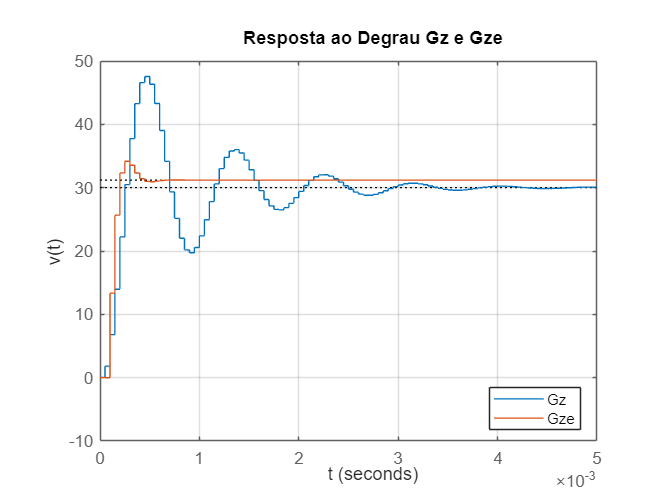


%Ganho_Gz = dcgain(Gz);
%Ganho_Gze = dcgain(Gze);
%K_corr = Ganho_Gz / Ganho_Gze; 
%Gze = Gze * K_corr;

figure(6)
clf;
step(Gz, Gze)
xlabel('t'); ylabel('v(t)');
grid on; 
legend('Gz', 'Gze', 'Location', 'best');
title('Resposta ao Degrau Gz e Gze');

disp('------------------------------------------------------');

------------------------------------------------------
